Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


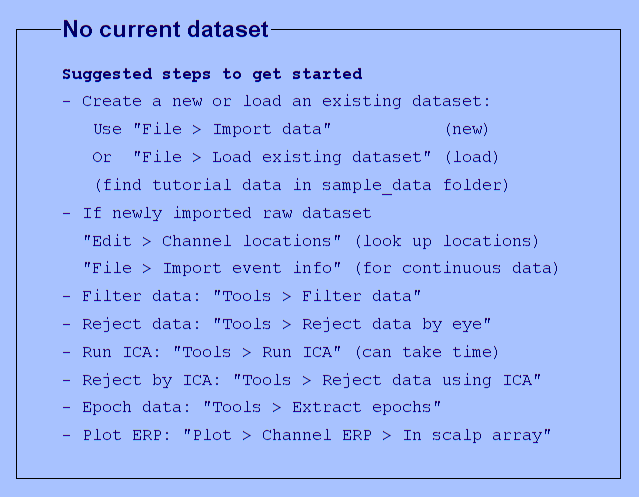

You are using the latest version of EEGLAB.


addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs\eeglab2023.0'
eeglab

imported_preproce_name =  'orig';
referenced_preproce_name =  'referenced';
imported_filename_ses_types = {'sleep1','sleep2','sleep3','sleep4','sleep5','wake_moring','wake_night'};
referenced_filename_ses_types = {'sleep','wake_moring','wake_night'};
imported_input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported';
imported_output_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\elaborated_events';
referenced_input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced'

referenced_input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced'

referenced_output_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\elaborated_events'

referenced_output_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\elaborated_events'

subs = {'01','02','03','04','05','06','07','08','09','10','11','12','13','14','15','16','17','19','20','21','22','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

% create elaborated event file for imported event files

for sub_ind=1:size(subs,2)
    for filename_ses_type_ind = 1:size(imported_filename_ses_types,2)
        output_filename = sprintf('%s//s_%s_%s_%s_elaboEvents.mat',imported_output_dir,subs{sub_ind},imported_filename_ses_types{filename_ses_type_ind},imported_preproce_name);
        if isfile(output_filename)
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end
    
        %% get imported file elaborated event table
        try
            set_filename = sprintf('%s\\s_%s_%s_%s.set',imported_input_dir,subs{sub_ind},imported_filename_ses_types{filename_ses_type_ind},imported_preproce_name)
            if isfile(set_filename)
                eeglab_imported =  pop_loadset(set_filename);
            end
        catch ME
            strcat('could not get ' ,set_filename)
            continue
        end 
        events_imported = eeglab_imported.event;
        if str2num(subs{sub_ind}) <= 8  || str2num(subs{sub_ind}) == 12
            has_omissions = false;
        else
            has_omissions = true;
        end
        try
            events = addEEGLABEvent_imported_trialInfo(events_imported, has_omissions);
        catch ME
            strcat('could not preform addEEGLABEvent_trialInfo for sub ' ,subs(sub_ind))
            continue
        end
        
        % Save the new eeglab event struct
        if ~isfolder(imported_output_dir)
            mkdir(imported_output_dir)
        end
        save(output_filename,"events");
    end
end

set_filename = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep1_orig.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\imported\s_01_sleep1_orig.set ...


% create elaborated event file for referenced event files
for sub_ind=1:size(subs,2)
    for filename_ses_type_ind = 1:size(referenced_filename_ses_types,2)
        output_filename = sprintf('%s//s_%s_%s_%s_elaboEvents.mat',referenced_output_dir,subs{sub_ind},referenced_filename_ses_types{filename_ses_type_ind},referenced_preproce_name);
        if isfile(output_filename)
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end
    
        %% get referenced file
        try
            set_filename = sprintf('%s\\s_%s_%s_%s.set',referenced_input_dir,subs{sub_ind},referenced_filename_ses_types{filename_ses_type_ind},referenced_preproce_name)
            if isfile(set_filename)
                eeglab_referenced =  pop_loadset(set_filename);
            end
        catch ME
            strcat('could not get ' ,set_filename)
            continue
        end 
        events_referenced = eeglab_referenced.event;
        events = addEEGLABEvent_referenced_trialInfo(events_referenced,imported_output_dir,subs{sub_ind});
        try
            %events = addEEGLABEvent_referenced_trialInfo(events_referenced);
        catch ME
            strcat('could not preform addEEGLABEvent_trialInfo for sub ' ,subs(sub_ind))
            continue
        end
        
        % Save the new eeglab event struct
        if ~isfolder(referenced_output_dir)
            mkdir(referenced_output_dir)
        end
        save(output_filename,"events");
    end
end

set_filename = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_01_sleep_referenced.set'

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_01_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_01_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


function [new_referenced_events] = addEEGLABEvent_referenced_trialInfo(events_referenced,imported_events_dir,sub)
    % Initialize new_referenced_events struct with new columns
    add_columns = {'preEpoched_filenum','tone_pos_in_trial','trial_pos_in_block',...
                    'block_pos_in_ses','sleep_stage','tone','TOA','omission_type_seniority','block_type'};
    new_referenced_events = events_referenced;
    zeros = cell(1,size(events_referenced,2));
    zeros(:) = {0};
    for i=1:size(add_columns,2)
        [new_referenced_events.(add_columns{i})] = zeros{:};
    end

    % assosiate each event with preEpoched file
    curr_nonepoched_file = 1;
    referenced_initTime = [events_referenced.init_time];
    new_referenced_events(1).('preEpoched_filenum') = 1;
    for epoched_i=2:size(events_referenced,2)
        if referenced_initTime(epoched_i - 1) > referenced_initTime(epoched_i)
            curr_nonepoched_file = curr_nonepoched_file + 1;
        end
        new_referenced_events(epoched_i).('preEpoched_filenum') = curr_nonepoched_file;
    end
   
    % populate event table with details
    curr_nonepoched_file_num = 0;
    for event_i=1:size(events_referenced,2)
        if new_referenced_events(event_i).preEpoched_filenum > curr_nonepoched_file_num
            curr_nonepoched_file_num = curr_nonepoched_file_num +1 ;
            curr_imported_events_filename = sprintf('%s\\s_%s_%s%s_%s_elaboEvents.mat',imported_events_dir,sub,"sleep",num2str(curr_nonepoched_file_num),"orig");
            curr_nonepoched_events = load(curr_imported_events_filename);
            curr_nonepoched_events = curr_nonepoched_events.events;
        end

        curr_nonepoched_urevents = [curr_nonepoched_events.urevent];
        tf1 = curr_nonepoched_urevents == new_referenced_events(event_i).init_index;
        ind = find(tf1);

        new_referenced_events(event_i).('tone_pos_in_trial') =curr_nonepoched_events(ind).('tone_pos_in_trial');
        new_referenced_events(event_i).('trial_pos_in_block') =curr_nonepoched_events(ind).('trial_pos_in_block');
        new_referenced_events(event_i).('block_pos_in_ses') =curr_nonepoched_events(ind).('block_pos_in_ses');
        new_referenced_events(event_i).('tone') =curr_nonepoched_events(ind).('tone');
        new_referenced_events(event_i).('TOA') =curr_nonepoched_events(ind).('TOA');
        new_referenced_events(event_i).('omission_type_seniority') =curr_nonepoched_events(ind).('omission_type_seniority');
        new_referenced_events(event_i).('block_type') =curr_nonepoched_events(ind).('block_type');
        new_referenced_events(event_i).('sleep_stage') =new_referenced_events(event_i).type(1:2);
    end
end



function [new_imported_events] = addEEGLABEvent_imported_trialInfo(events_imported,has_omissions)
    % Initialize new_epoched_event struct
    add_columns = {'tone_pos_in_trial','trial_pos_in_block',...
                    'block_pos_in_ses','sleep_stage','tone','TOA','omission_type_seniority','block_type'};
    new_imported_events = events_imported;
    zeros = cell(1,size(events_imported,2));
    zeros(:) = {0};
    for i=1:size(add_columns,2)
        [new_imported_events.(add_columns{i})] = zeros{:};
    end

    curr_block_pos_in_ses = 0;
    curr_omission_type_seniority = 1;
    list_of_type = {events_imported.type};
    curr_block_type = '0';
    
    % populate event table with ss details
    for event_i=2:size(events_imported,2)
        if any(strcmp(events_imported(event_i).type, {'STRT','break cnt','SEND','net'}))
            continue;
        end
        if strcmp(events_imported(event_i).type, 'BGIN')
            if ~has_omissions || event_i+21 > size(events_imported,2)
                curr_omission_type_seniority = 0;   
                curr_block_type = 0;
            elseif any(startsWith({list_of_type{event_i:event_i+21}}, 'O') & endsWith({list_of_type{event_i:event_i+21}}, '9'))
                if strcmp(curr_block_type,'random')
                    curr_omission_type_seniority = 0;
                end
                curr_block_type = 'fixed';
            else
                if strcmp(curr_block_type,'fixed')
                    curr_omission_type_seniority = 0;
                end
                curr_block_type = 'random';
            end
            curr_block_pos_in_ses = curr_block_pos_in_ses +1;
            curr_trial_pos_in_block = 0;
            continue;
        end
        if strcmp(events_imported(event_i).type, 'A500_0')
            curr_trial_pos_in_block = curr_trial_pos_in_block+1;
            curr_omission_type_seniority = curr_omission_type_seniority+1;
        end

        new_imported_events(event_i).('block_pos_in_ses') =curr_block_pos_in_ses;
        new_imported_events(event_i).('trial_pos_in_block') =curr_trial_pos_in_block;
        new_imported_events(event_i).('omission_type_seniority') =curr_omission_type_seniority;
        
        new_imported_events(event_i).('tone_pos_in_trial') = str2double(events_imported(event_i).type(end)) +1;
        new_imported_events(event_i).('TOA') = events_imported(event_i).type(1);
        
        new_imported_events(event_i).('block_type') = curr_block_type;

        splitted_type = split( events_imported(event_i).type,"_");
        new_imported_events(event_i).('tone') = splitted_type{1}(2:end);
    end
end

